gyrodata = readtable('output_gyro.txt')

gyrodata = 747×1 table
    Var1
    ____

    1.73
    1.74
    1.75
    1.77
    1.78
    1.79
     1.8
    1.81
    1.82
    1.83
    1.84
    1.84
    1.85
    1.86
    1.86
    1.87


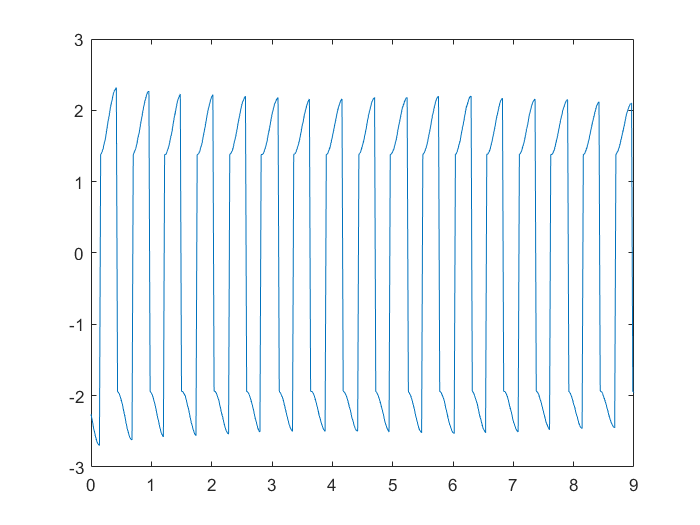

angles = gyrodata.Var1;
angles = angles - 0.28;
t = 0:0.02:20;

t = t(1:length(angles))';
angles = angles(150:600);
t = t(150:600) - t(150);
plot(t, angles)

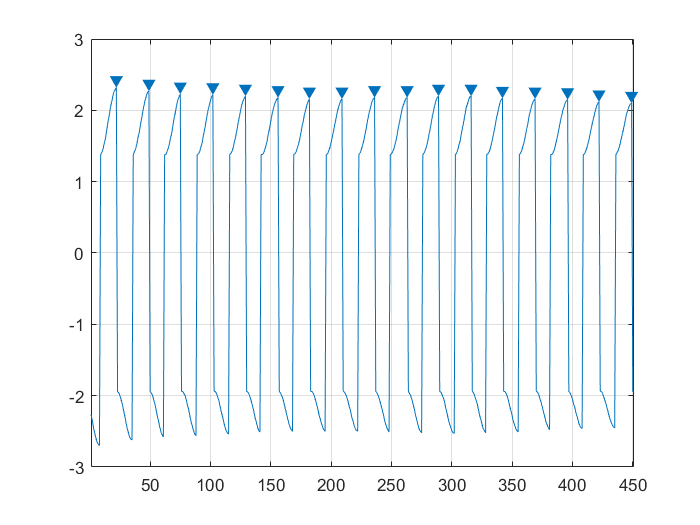

findpeaks(angles)

[pks, locs] = findpeaks(angles)

pks =     2.3200
    2.2700
    2.2300
    2.2200
    2.2000
    2.1800
    2.1600
    2.1600
    2.1800
    2.1800


locs =     22
    49
    75
   102
   129
   156
   182
   209
   236
   263


times_pks = t(locs)

times_pks =     0.4200
    0.9600
    1.4800
    2.0200
    2.5600
    3.1000
    3.6200
    4.1600
    4.7000
    5.2400


period_sd = std(diff(times_pks))

period_sd = 0.0096

period = mean(diff(times_pks))

period = 0.5338

wn = 2*pi/period

wn = 11.7718


l_eff = 9.81/wn^2

l_eff = 0.0708